addpath('C:\Users\filip\Desktop\investments_f\Functions') % path to get the functions for the models and the backtest function
addpath('C:\Users\filip\Desktop\investments_f\Datasets') % path to get datasets

clear
close
clc

returns = readtable("EUROSTOXX50_ret_backtest.xlsx");

tickers = returns.Properties.VariableNames(2:end);
returns = table2array(returns(:, 2:end));

DL = 750;
DH = 20;

% data cutting
returns = returns(751-DL:end, :);

% Backtest
[Wealth_Ptf, R_Ptf_out, Weights] = F_Backtester_MaxArea(returns,DL,DH);

% % Putting the index in the final Table
% IP = IndexPrice(end+1-size(Wealth_Ptf):end); % index price for the same days as the ptf
% IndexLevel = IP./IP(1);
% IndexLevel = table(IndexLevel);
% Wealth_Ptf = [Wealth_Ptf IndexLevel]; % insert in the final table also Index as the last column
% % Saving the Time of the whole strategy
% Time = Time(end-size(Wealth_Ptf,1)+1:end,:);

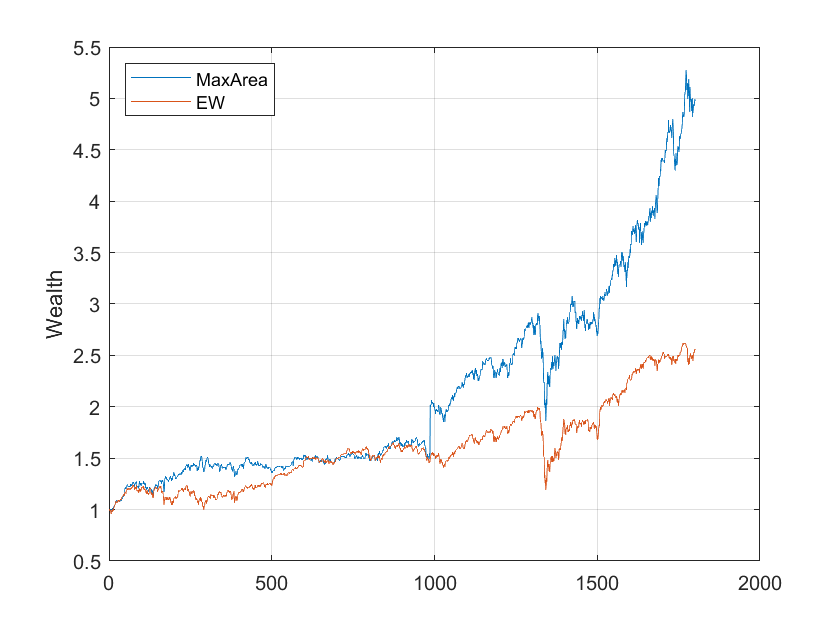

Model_Names = Wealth_Ptf.Properties.VariableNames;
Model_Names = regexprep(Model_Names, '_', ' ');
Wealth_to_plot = table2array(Wealth_Ptf);
figure
plot(Wealth_to_plot)
legend(Model_Names,'Location','northwest')
ylabel('Wealth')
grid

% Performance analysis
[Performance_Analysis] = F_Performance_Analysis(Wealth_Ptf)

Performance_Analysis = 2×15 table
               Total Return        mu        Volatility    Sharpe Ratio    Sortino Ratio    Rachev Ratio 5%    Rachev Ratio 10%    Average DD    CDaR 95%    Max DD     CVaR 95%    Ulcer Index    Pitfall Indicator    Penalized Risk    Serenity Ratio
               ____________    __________    __________    ____________    _____________    _______________    ________________    __________    ________    _______    ________    ___________    _________________    ______________

% Saving output outside
writetable(Performance_Analysis, '2022_01_22_EUROSTOXX_PerformanceTable_750_20.xlsx')